clear
scenario = robotScenario(UpdateRate=1, StopTime=10);
addpath("C:\Users\dnehu\Documents\University\Year 3\Engineering\MECH3465 - Robotics & Machine Intelligence\Robotics\Coursework 2\URDFs\Robot_URDF\urdf")  % Dan path folder
savepath 
robotRBT = importrobot("Robot_URDF.urdf");
robotRBT.DataFormat = "row";  % or use "column" if you prefer

% Create the robotPlatform for the manipulator
Robot = robotPlatform("Manipulator", scenario, RigidBodyTree=robotRBT);

%% Update Book Definitions for Shelf Placement on the Shelf
% Shelf coordinates for the bottom of the books in the desired order:
% Order: Red, Purple, Green, Orange, Yellow, Blue.
% (Coordinates are in meters.)
shelf_coords = [ -0.247203, -0.0888485, 0.17703;   % Red (bottom)
                 -0.125306,  0.229985, 0.17703;    % Purple (bottom)
                 -0.230686,  0.122,    0.17703;    % Green (bottom)
                 -0.26,     -0.015964705, 0.17703;   % Orange (bottom)
                 -0.256188,  0.0580598,  0.17703;    % Yellow (bottom)
                 -0.184746,  0.186741,   0.17703];   % Blue (bottom)

% Book dimensions [width, depth, height] (in meters)
book_size = [0.025, 0.1, 0.07];

% Since the robot platforms use the center of the book, compute the offset.
% The offset is half the height in Z.
book_center_offset = [0, 0, book_size(3)/2 + 0.0151];  % [0, 0, 0.035]
% Compute the center positions for each book.
book_centers = shelf_coords + repmat(book_center_offset, size(shelf_coords,1), 1);

% Compute desired yaw angles such that books face outward from the shelf center (assumed at the origin).
% Here we add pi to flip the direction.
desired_yaws = zeros(size(book_centers,1),1);
for i = 1:size(book_centers,1)
    desired_yaws(i) = wrapToPi(atan2(book_centers(i,2), book_centers(i,1)) + pi);
end

% Convert desired yaw angles into quaternions (rotation about Z-axis).
book_quats = zeros(size(book_centers,1), 4);
for i = 1:size(book_centers,1)
    book_quats(i,:) = axang2quat([0, 0, 1, desired_yaws(i)]);
end

% Apply extra fixed rotations:
%   - A rotation about X by -45° (to have the book on its short edge)
%   - A rotation about Y by 90° (to further orient the book)
fixedQuatX = axang2quat([1, 0, 0, -pi/2]);    % -45° about X-axis
fixedQuatY = axang2quat([0, 1, 0, pi/2]);       % 90° about Y-axis

% Combine the fixed rotations. The order is important: here we apply the X rotation then the Y rotation.
combinedFixed = quatMultiply(fixedQuatX, fixedQuatY);

% Now, combine each computed book quaternion with the fixed rotation.
final_book_quats = zeros(size(book_quats));
for i = 1:size(book_quats,1)
    final_book_quats(i,:) = quatMultiply(book_quats(i,:), combinedFixed);
end

% Define the book colors in the desired order: Red, Purple, Green, Orange, Yellow, Blue.
book_colors = [1 0 0;         % Red
               0.5 0 0.5;     % Purple
               0 1 0;         % Green
               1 0.5 0;       % Orange
               1 1 0;         % Yellow
               0 0 1];        % Blue

% Create book platforms using the new positions and orientations.
book_1 = robotPlatform("Book_1", scenario, 'Collision', "mesh", ...
    'InitialBaseOrientation', final_book_quats(1,:), 'InitialBasePosition', book_centers(1,:));
updateMesh(book_1, "Cuboid", 'Collision', "mesh", 'Size', book_size, 'Color', book_colors(1,:));

book_2 = robotPlatform("Book_2", scenario, 'Collision', "mesh", ...
    'InitialBaseOrientation', final_book_quats(2,:), 'InitialBasePosition', book_centers(2,:));
updateMesh(book_2, "Cuboid", 'Collision', "mesh", 'Size', book_size, 'Color', book_colors(2,:));

book_3 = robotPlatform("Book_3", scenario, 'Collision', "mesh", ...
    'InitialBaseOrientation', final_book_quats(3,:), 'InitialBasePosition', book_centers(3,:));
updateMesh(book_3, "Cuboid", 'Collision', "mesh", 'Size', book_size, 'Color', book_colors(3,:));

book_4 = robotPlatform("Book_4", scenario, 'Collision', "mesh", ...
    'InitialBaseOrientation', final_book_quats(4,:), 'InitialBasePosition', book_centers(4,:));
updateMesh(book_4, "Cuboid", 'Collision', "mesh", 'Size', book_size, 'Color', book_colors(4,:));

book_5 = robotPlatform("Book_5", scenario, 'Collision', "mesh", ...
    'InitialBaseOrientation', final_book_quats(5,:), 'InitialBasePosition', book_centers(5,:));
updateMesh(book_5, "Cuboid", 'Collision', "mesh", 'Size', book_size, 'Color', book_colors(5,:));

book_6 = robotPlatform("Book_6", scenario, 'Collision', "mesh", ...
    'InitialBaseOrientation', final_book_quats(6,:), 'InitialBasePosition', book_centers(6,:));
updateMesh(book_6, "Cuboid", 'Collision', "mesh", 'Size', book_size, 'Color', book_colors(6,:));

hold off

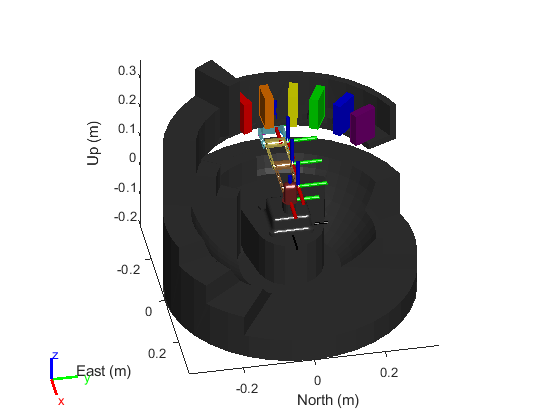

[ax,plotFrames] = show3D(scenario,Collisions="off");
axis equal
hold on
view(79,36)
light
hold off


%% Compute Final Book Positions and Orientations

% Define the shelf coordinates (bottom of each book, in meters)
% Order: Red, Purple, Green, Orange, Yellow, Blue
shelf_coords = [ 
    -0.247203, -0.0888485, 0.17703;
    -0.125306,  0.229985,  0.17703;
    -0.230686,  0.122,     0.17703;
    -0.26,     -0.015964705, 0.17703;
    -0.256188,  0.0580598,  0.17703;
    -0.184746,  0.186741,   0.17703
];

% Define the book dimensions: [width, depth, height] in meters
book_size = [0.025, 0.1, 0.07];

% Compute the offset to shift from the bottom position to the book center
% Offset in Z is half the book height plus a fixed extra offset
book_center_offset = [0, 0, book_size(3)/2 + 0.0151];  % ≈ [0, 0, 0.0501]

% Compute the final book centers
book_centers = shelf_coords + repmat(book_center_offset, size(shelf_coords,1), 1);

% Compute desired yaw for each book so they face outward
% The yaw is computed as the angle from the shelf center (origin) to the book center plus pi
desired_yaws = zeros(size(book_centers,1), 1);
for i = 1:size(book_centers,1)
    desired_yaws(i) = wrapToPi(atan2(book_centers(i,2), book_centers(i,1)) + pi);
end

% Convert the desired yaw angles into quaternions (rotation about Z-axis)
book_quats = zeros(size(book_centers,1), 4);
for i = 1:size(book_centers,1)
    book_quats(i,:) = axang2quat([0, 0, 1, desired_yaws(i)]);
end

% Define fixed extra rotations:
% - Rotate about X by -45° (to have the book on its short edge)
% - Rotate about Y by 90° (to further orient the book)
fixedQuatX = axang2quat([1, 0, 0, -pi/4]);  % -45° about X-axis
fixedQuatY = axang2quat([0, 1, 0, pi/2]);   % 90° about Y-axis

% Combine the fixed rotations (order matters)
combinedFixed = quatMultiply(fixedQuatX, fixedQuatY);

% Combine each computed book quaternion with the fixed rotation
final_book_quats = zeros(size(book_quats));
for i = 1:size(book_quats,1)
    final_book_quats(i,:) = quatMultiply(book_quats(i,:), combinedFixed);
end

% Display the final results
disp('Final book center coordinates:');

Final book center coordinates:


disp(book_centers);

   -0.2472   -0.0888    0.2271
   -0.1253    0.2300    0.2271
   -0.2307    0.1220    0.2271
   -0.2600   -0.0160    0.2271
   -0.2562    0.0581    0.2271
   -0.1847    0.1867    0.2271




disp('Final book orientations (quaternions):');

Final book orientations (quaternions):


disp(final_book_quats);

    0.6900   -0.3787    0.5971   -0.1544
    0.4235    0.1010    0.6999   -0.5663
    0.5689   -0.1053    0.6992   -0.4200
    0.6613   -0.2905    0.6447   -0.2504
    0.6191   -0.1963    0.6793   -0.3416
    0.4987    0.0019    0.7071   -0.5013



function q = quatMultiply(q1, q2)
    % quatMultiply multiplies two quaternions q1 and q2.
    % Both q1 and q2 should be 1x4 vectors in the format [w, x, y, z].
    w1 = q1(1); x1 = q1(2); y1 = q1(3); z1 = q1(4);
    w2 = q2(1); x2 = q2(2); y2 = q2(3); z2 = q2(4);
    w = w1*w2 - x1*x2 - y1*y2 - z1*z2;
    x = w1*x2 + x1*w2 + y1*z2 - z1*y2;
    y = w1*y2 - x1*z2 + y1*w2 + z1*x2;
    z = w1*z2 + x1*y2 - y1*x2 + z1*w2;
    q = [w, x, y, z];
end